clc; clear; close all;

%% System matrices from linearized model
A = [0 0 1 0;
     0 0 0 1;
     0 16.5917 0 0;
     0 105.5970 0 0];

B = [0;
     0;
     1475.6369;
     1173.3223];

C = [0 1 0 0];   % output = theta_2
D = 0;

sys = ss(A,B,C,D);

%% 1) Check controllability
Co = ctrb(A,B);
rank_Co = rank(Co);

disp('Controllability matrix rank:')

Controllability matrix rank:


disp(rank_Co)

     4




if rank_Co == size(A,1)
    disp('System is controllable -> pole placement can be used.')
else
    error('System is NOT controllable. Pole placement cannot be used directly.')
end

System is controllable -> pole placement can be used.



%% 2) Choose desired closed-loop poles
p_des = [-5 -6 -7 -8];

%% 3) Compute state feedback gain
K = place(A,B,p_des);

disp('State feedback gain K =')

State feedback gain K =


disp(K)

   -0.0123    0.3194   -0.0078    0.0320




%% 4) Closed-loop system
A_cl = A - B*K;
sys_cl = ss(A_cl,B,C,D);

cl_poles = eig(A_cl);

disp('Closed-loop poles:')

Closed-loop poles:


disp(cl_poles)

   -8.0000
   -7.0000
   -6.0000
   -5.0000




%% Stability check
if all(real(cl_poles) < 0)
    disp('Closed-loop system is asymptotically stable.')
else
    disp('Closed-loop system is NOT asymptotically stable.')
end

Closed-loop system is asymptotically stable.



%% Damping information
disp('Damping information:')

Damping information:


damp(sys_cl)

                                                           
   Pole        Damping       Frequency      Time Constant  
                           (rad/seconds)      (seconds)    
                                                           
 -5.00e+00     1.00e+00       5.00e+00         2.00e-01    
 -6.00e+00     1.00e+00       6.00e+00         1.67e-01    
 -7.00e+00     1.00e+00       7.00e+00         1.43e-01    
 -8.00e+00     1.00e+00       8.00e+00         1.25e-01    


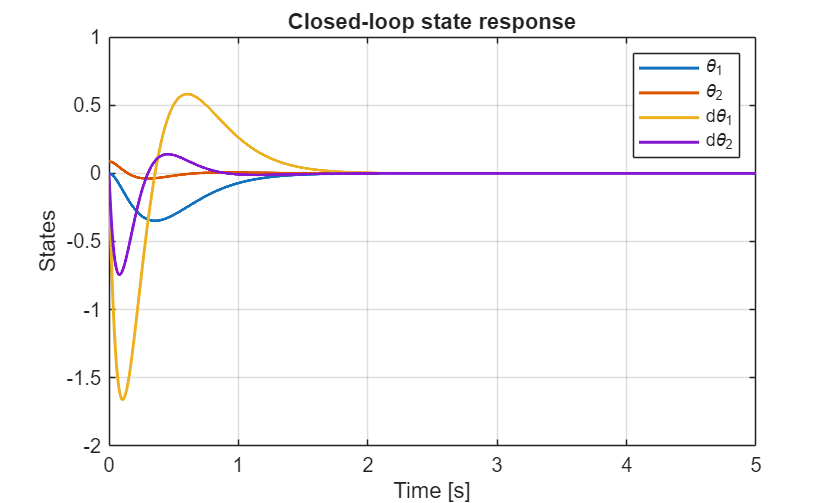


%% 5) Simulate initial-condition response
x0 = [0; deg2rad(5); 0; 0];   % initial pendulum deviation
t = 0:0.001:5;

[y,t,x] = initial(sys_cl,x0,t);

figure;
plot(t, x(:,1), 'LineWidth', 1.5); hold on;
plot(t, x(:,2), 'LineWidth', 1.5);
plot(t, x(:,3), 'LineWidth', 1.5);
plot(t, x(:,4), 'LineWidth', 1.5);
grid on;
xlabel('Time [s]')
ylabel('States')
legend('\theta_1','\theta_2','d\theta_1','d\theta_2')
title('Closed-loop state response')

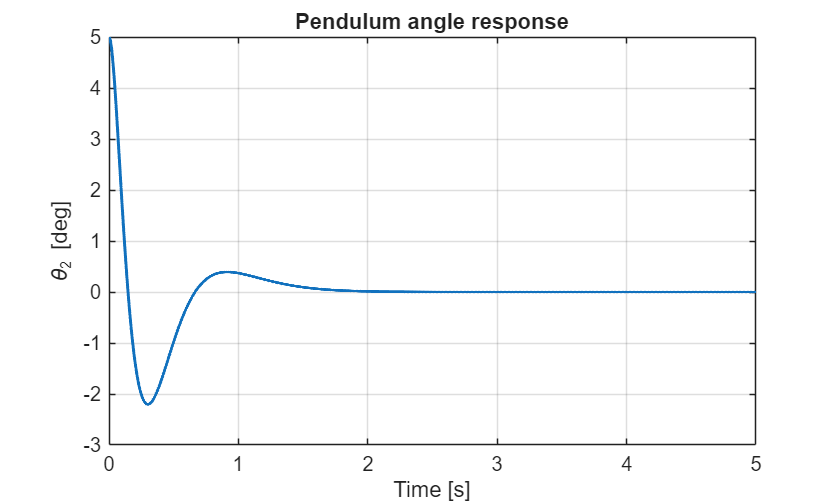


figure;
plot(t, rad2deg(x(:,2)), 'LineWidth', 1.5);
grid on;
xlabel('Time [s]')
ylabel('\theta_2 [deg]')
title('Pendulum angle response')

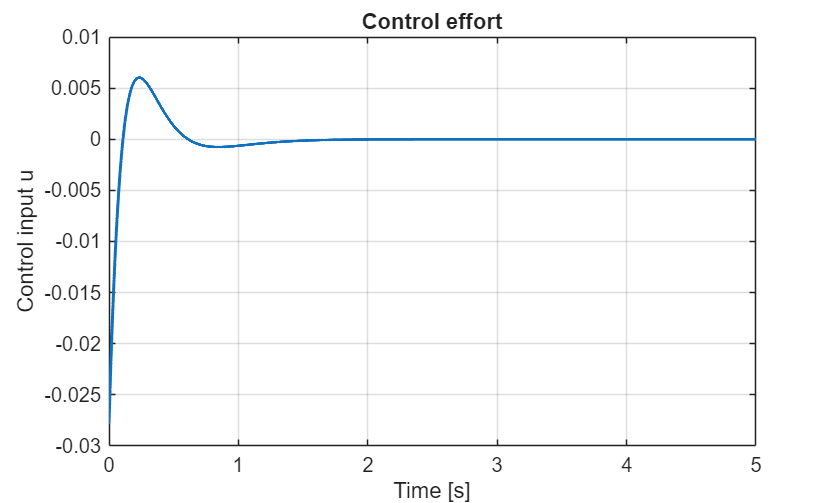


%% 6) Compute control effort u(t) = -Kx(t)
u = zeros(length(t),1);
for i = 1:length(t)
    u(i) = -K*x(i,:)';
end

figure;
plot(t, u, 'LineWidth', 1.5);
grid on;
xlabel('Time [s]')
ylabel('Control input u')
title('Control effort')


%% 7) Performance measures
theta2_deg = rad2deg(x(:,2));
max_angle = max(abs(theta2_deg));
max_u = max(abs(u));

% Approximate settling time: when theta_2 stays within 2% of initial angle
theta_ref = abs(rad2deg(x0(2)));
tol = 0.02 * theta_ref;

idx_settle = find(abs(theta2_deg) <= tol, 1, 'first');
if isempty(idx_settle)
    settling_time = NaN;
else
    settling_time = t(idx_settle);
end

disp('Performance measures:')

Performance measures:


fprintf('Maximum pendulum angle deviation: %.3f deg\n', max_angle);

Maximum pendulum angle deviation: 5.000 deg


fprintf('Maximum control effort: %.3f\n', max_u);

Maximum control effort: 0.028


fprintf('Approx. settling time: %.3f s\n', settling_time);

Approx. settling time: 0.145 s
